Keanu Francis

Z#23456741  

Assignment 2 - Imagle Labeler

## Loading Unlabled Data

From the Documentation i loaded the books dataset and added labes for the book the title and author. Though this was not done for every book 

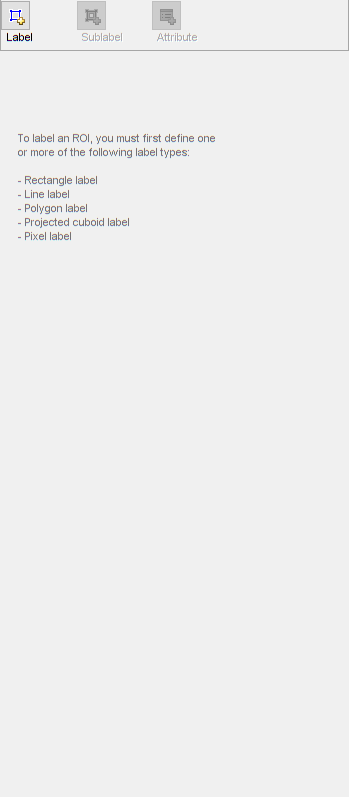

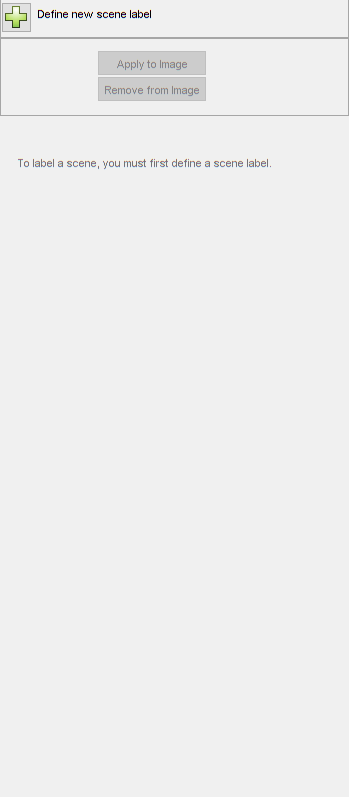

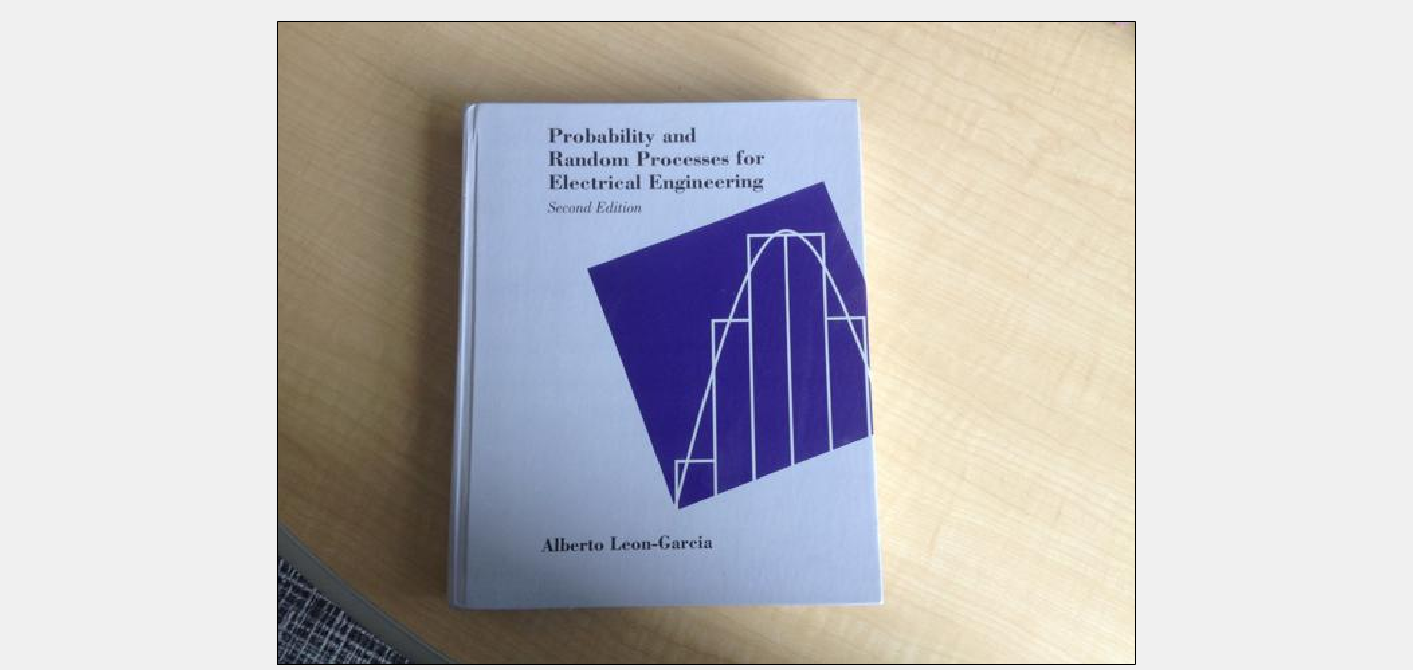

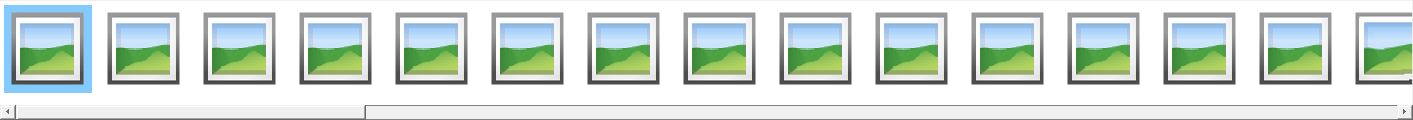

imageFolder = fullfile(toolboxdir('vision'),'visiondata','bookcovers');
imds = imageDatastore(imageFolder);
imageLabeler(imds);

### Loading book gtruth 

The gtruth file can either be saved in the workspace or as a file in this case we will save it as a file called 'gtruthBooks.mat' and load it into the workspace

gtruthBooks = load("gtruthBooks.mat")

gtruthBooks = struct with fields:
    gTruth: [1×1 groundTruth]


gtruthBooks=gtruthBooks.gTruth

gtruthBooks =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [1×6 table]
           LabelData: [58×1 table]


gtruthBooks.DataSource

ans = groundTruthDataSource for an image collection with properties

                      Source: {
                              ' ...\MATLAB\R2022b\toolbox\vision\visiondata\bookcovers\book1.jpg';
                              ' ...\MATLAB\R2022b\toolbox\vision\visiondata\bookcovers\book10.jpg';
                              ' ...\MATLAB\R2022b\toolbox\vision\visiondata\bookcovers\book11.jpg'
                               ... and 55 more
                              }

gtruthBooks.LabelDefinitions

ans = 1×6 table
      Name         Type               LabelColor             Group      Description    Hierarchy 
    _________    _________    __________________________    ________    ___________    __________

    {'Books'}    Rectangle    0.5862    0.8276    0.3103    {'None'}    {0×0 char}     1×1 struct


## Loading our Own data

Would like to perform a similar operation with the labeling of faces.

in this case we will use the data set provided from kaggle this time we will labeling only the mouth then using these labels to train an object detection algorythm.

fData=imageDatastore("Faces");
imageLabeler(fData);

## Gtruth data

After saving the data to a file we can the review the information

gtruthFaces= load('facegtruth.mat');
gtruthFaces=gtruthFaces.gTruth
gtruthFaces.LabelDefinitions

## Training detector

Next we can train the trainACFObjectDetector using these images and labels

load("mouthgtruth.mat")
mouthGtruth= selectLabelsByName(gTruth,'mouth');
traininData= objectDetectorTrainingData(mouthGtruth);
detector=trainACFObjectDetector(traininData,'NumStages',5);
save('Detector.mat','detector');

## Testing Detecter

we can now test the train the detecter to see if it can correctly identify mouths of other images we can use a picture from the test data file.

load("Detector.mat")
i=imread("TestData\1 (281).jpg");
bboxes=detect(detector,i)
annotation = detector.ModelName;
i = insertObjectAnnotation(i,'rectangle',bboxes,annotation);
figure 
imshow(i)
